G=[
   0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 1 1 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0; 
   ]

G =      0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0


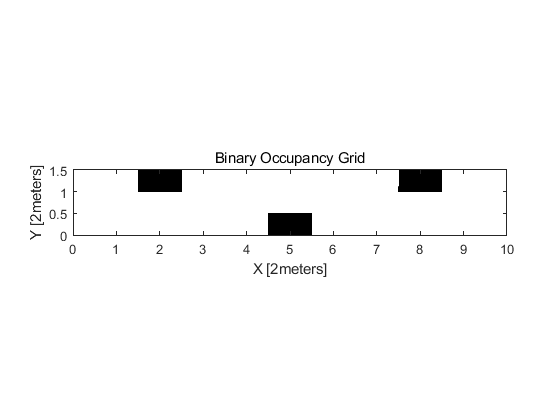

map = binaryOccupancyMap(G,2);
show(map)

xlabel('X [2meters]')
ylabel('Y [2meters]')

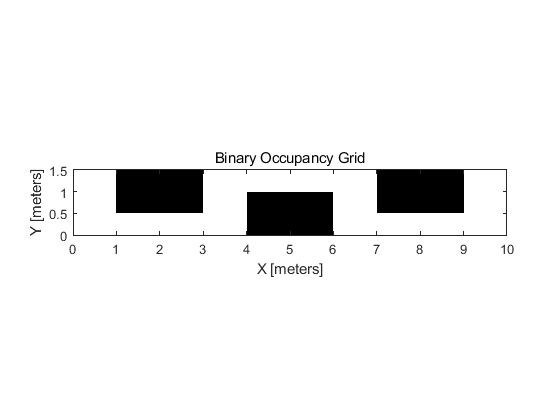

robotRadius = 0.5;

mapInflated = copy(map);
inflate(mapInflated,robotRadius);

show(mapInflated)

prm = mobileRobotPRM;
prm.Map = mapInflated;
prm.NumNodes = 50;
prm.ConnectionDistance = 5;

startLocation = [0.5 1.25];
endLocation = [9.5 1.25];
path = findpath(prm, startLocation, endLocation)

path =     0.5000    1.2500
    0.4406    1.0921
    1.0796    0.3535
    2.8287    0.1956
    3.4512    1.0702
    5.9747    1.0273
    7.3731    0.2300
    8.1135    0.1432
    9.4162    0.5901
    9.3576    1.3222


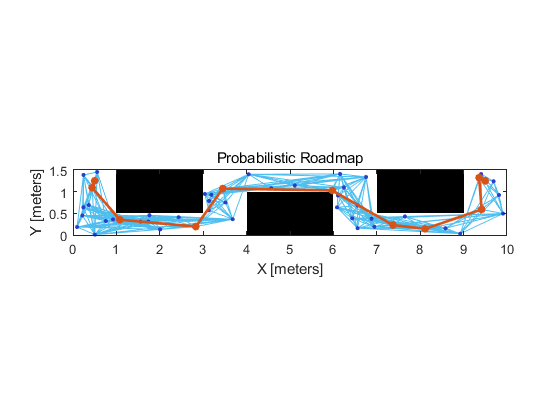

show(prm)